clc;
clear all;
close all;

## Formula1 -drive to survive 

% take note of the car drifting
% I figured out I can make the car drift by messing with the zbearing code.
% I realized I could take the regular code of zbea=m and add a parabola to
% it making it zbea=m-m*(m-2*pi)*a (only if m=0:01:2*pi)
% this allows it to start at the normal beaing it should be at when m=0 and
% for it to end up in the same location at m=2*pi
%for this case, the a is a scalar factor that controlls how radical the
%drifting it

% take note of the car accelerating in the beginning
%this is done by messing with the pause function
% see instead of making it pause(.001) like how I coded it for most other
% things, I realized I could start a pause of like .0018 sec per frame then
% I could shrink the frame duration by a log function making it
% pause(.0018-log(i+1)*.0004). This gives the illusion that the car is
% speeding up.


% take note of the screen opening up in full view
% I used a lot of set commands in this project. Like to render the objects
% or to set the black backround but the one set command that was real
% practical was the one that made the screen pop up in full view.


% also another trick I used that was real helpful was when I was coding the
% movement, I realized I could recall the last movement by accessing the
% last term of the vector that controlls the previous movement for the
% object.  So if im coding movement 13 I can start it with
% xmove12(length(xmove12)) which will give the x coordinate of the previous
% move

## axis codes

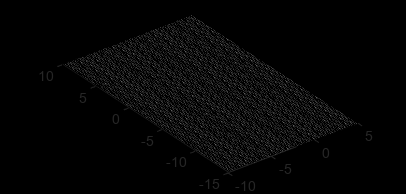

ax = axes('XLim',[-15 2],'YLim',[-15 10],'ZLim',[-1.5 1.5]);
view(3);
grid off;
axis equal;

[Xg,Yg] = meshgrid(-10:.2:5, -15:.2:10);
Zg =.00001*Xg+.0001*Yg;
surf(Xg,Yg,Zg)
colormap white
axis equal

set(gcf,'Color','black')

scrsz = get(0,'ScreenSize');
set(gcf,'Position',[scrsz(1) scrsz(2)+scrsz(4)/20 scrsz(3) scrsz(4)*17/20]);

## object codes

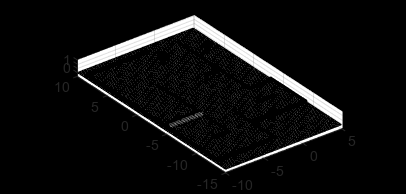

[xs,ys,zs]=sphere(20);
[yb, xb, zb]=cylinder([.4 0]);
[yt, xt, zt]=cylinder([.2 .2]);
[yf, xf, zf]=cylinder([.1 .1]);
[xbb, ybb, zbb]=cylinder([.3 .3]);




g(1) = surface(.5*yb-7,.5*xb-9,.5*zb,'FaceColor','black');
g(2) = surface(.5*xs+3,.5*ys+5,.5*zs+1,'faceColor','g');
g(3) = surface(xt+3,yt+5,zt,'FaceColor','yellow');
g(4) = surface(.5*xs-2,.5*ys+6,.5*zs+1,'FaceColor','green');
g(5) = surface(xt-2,yt+6,zt,'FaceColor','yellow');
g(6) = surface(xf-.8,yf+.2,zf,'FaceColor','black');
g(7) = surface(xf+.8,yf+.2,zf,'FaceColor','black');
g(8) = surface(1.4*zf-.7,1.4*xf+.2,1.4*yf+1,'FaceColor','white');
g(9) = surface(.2*xs+.8,.2*ys+.2,.2*zs+1,'FaceColor','white');
g(10) = surface(.2*xs-.8,.2*ys+.2,.2*zs+1,'FaceColor','white');
g(11) = surface(.5*yb-2,.5*xb-6,.5*zb,'FaceColor','white');
g(12) = surface(.5*yb+1,.5*xb-6,.5*zb,'FaceColor','black');
g(13) = surface(.5*yb+3,.5*xb-6,.5*zb,'FaceColor','black');
g(14) = surface(.5*yb+2,.5*xb-3.3,.5*zb,'FaceColor','black');
g(15) = surface(.5*xbb-5,12*zbb-9,.5*ybb,'FaceColor','white');
g(16) = surface(.5*xbb-9.5,22*zbb-13,.5*ybb,'FaceColor','white');
g(17) = surface(7*zbb-9.5,.5*ybb-13,.5*xbb,'FaceColor','white');
g(18) = surface(8*zbb-9.5,.5*ybb+9,.5*xbb,'FaceColor','white');
g(19) = surface(7*zbb-2,.5*ybb-9,.5*xbb,'FaceColor','white');
g(20) = surface(.5*xbb-2,7*zbb-13,.5*ybb,'FaceColor','white');
g(21) = surface(.5*xbb+2,12*zbb-3.3,.5*ybb,'FaceColor','white');
g(22) = surface(2*zbb+1,.5*ybb-6,.5*xbb,'FaceColor','white');
g(23) = surface(2*zbb-7,.5*ybb-9,.5*xbb,'FaceColor','white');
g(24) = surface(3.*zbb+1.9,.5*ybb-3.3,.5*xbb,'FaceColor','white');
g(25) = surface(.5*xs,.5*ys-10,.5*zs+1,'FaceColor','green');
g(26) = surface(xt,yt-10,zt,'FaceColor','yellow');
g(27) = surface(.5*xbb+5,6*zbb-9,.5*ybb,'FaceColor','white');
g(28) = surface(4.5*zbb-9.5,1.5*ybb-4.5,1.5*xbb,'FaceColor','white');

t = hgtransform('Parent',ax);
set(g,'Parent',t)
set(gcf,'Renderer','opengl')

drawnow

## car codes

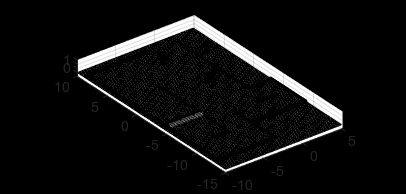

[xt,yt,zt] = ellipsoid(0,0,0,.35,.2,.25);
[xw, yw, zw]=cylinder(.1);
[xb, yb, zb]=cylinder(.25);

h(1) = surface(yb,zb,xb,'FaceColor','red');
h(2) = surface(zw-.5,yw+.8,xw,'FaceColor','black');
h(3) = surface(zw-.5,yw+.2,xw,'FaceColor','black');
h(4) = surface(yt,-xt+.5,zt+.15,'FaceColor','red');


t = hgtransform('Parent',ax);
set(h,'Parent',t)
set(gcf,'Renderer','opengl')

drawnow

## moving codes

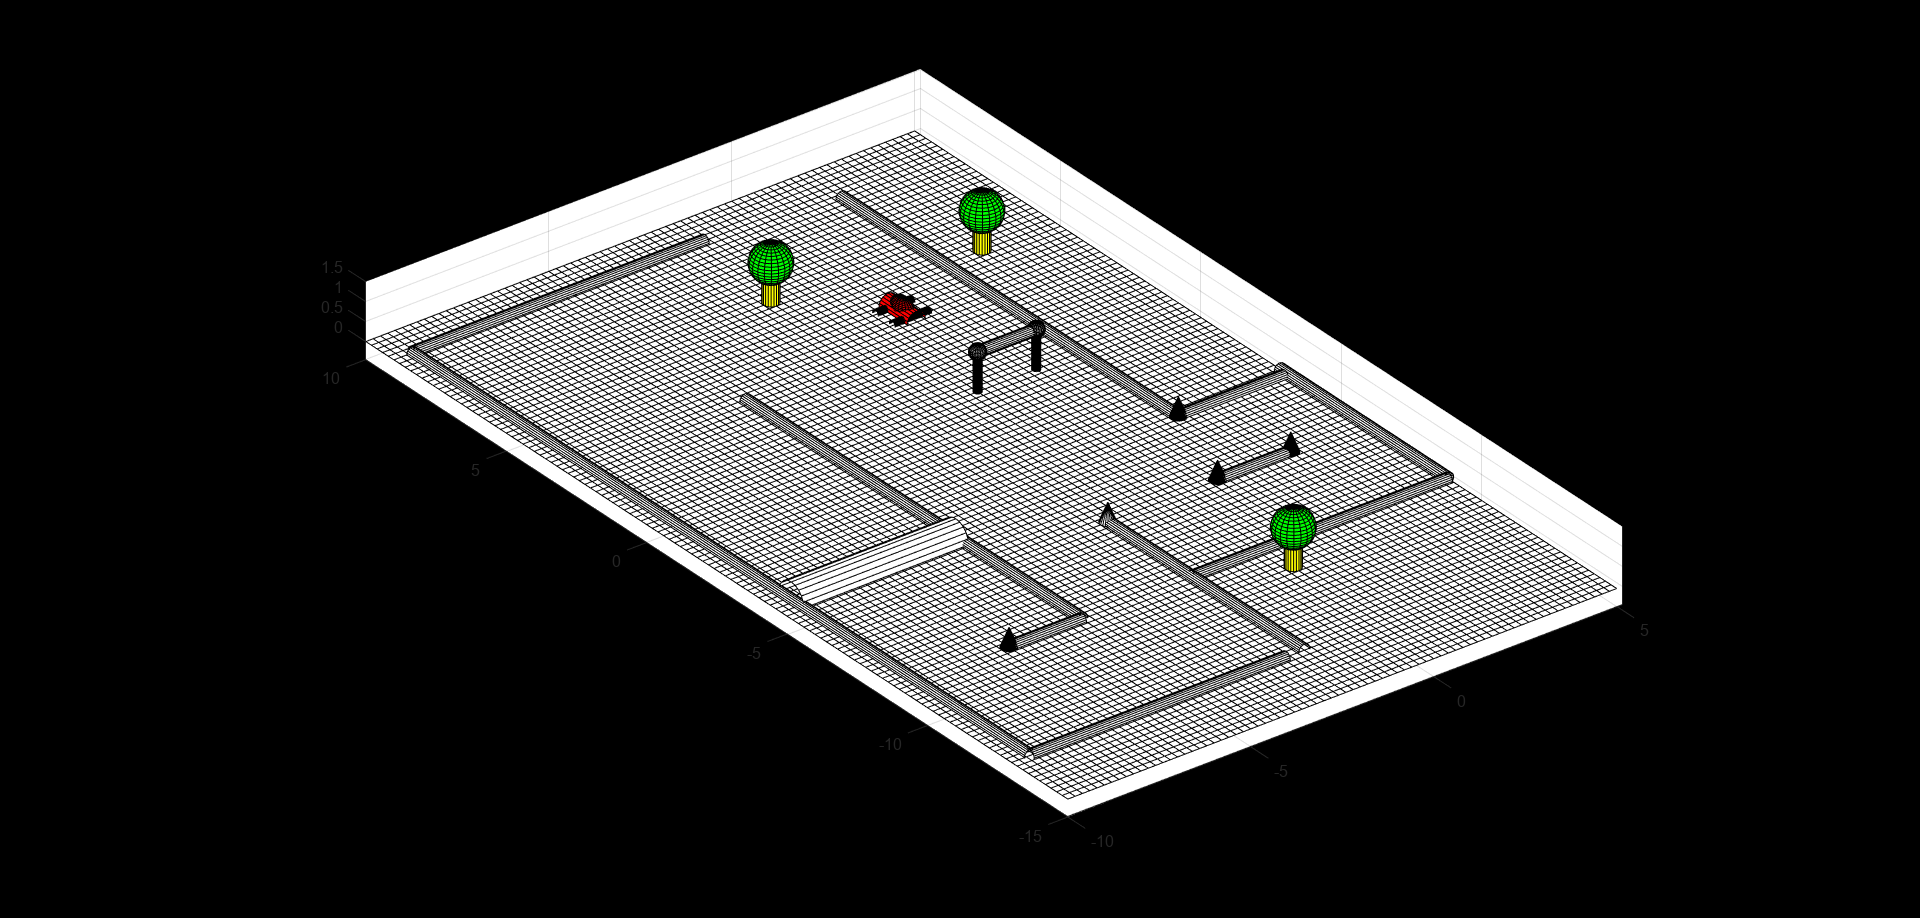

for i=1
    %d=text(7,0,1,num2str(6-i),'FontSize',30,'BackgroundColor',[1 1 1]);
    d=text(7,0,1,'\fontsize{16} {\color{red}3}');
    pause(1)
    delete(d)
    d=text(7,0,1,'\fontsize{16} {\color{red}2}');
    pause(1)
    delete(d)
    d=text(7,0,1,'\fontsize{16} {\color{green}1}');
    pause(1)
    delete(d)
    d=text(7,0,1,'\fontsize{16} {\color{green}start}');
    pause(1)
    delete(d)
end



m=0:.07:6;
xmove=zeros(1,length(m));
ymove=m;

for i=1:numel(xmove)
    trans=makehgtform('translate',[xmove(i) ymove(i) 0]);
    set(t,'matrix',trans);
    pause(.0018-log(i+1)*.0004)
end



m=0:.05:3/4*pi;
xmove=2*cos(m)-2;
ymove=2*sin(m)+6;
zbea=m-m.*(m-3*pi/4);

for i=1:numel(xmove)
    trans=makehgtform('translate',[xmove(i) ymove(i) 0]);
    rotz=makehgtform('zrotate',zbea(i));
    set(t,'matrix',trans*rotz);
    pause(.001)
end




m=0:.25:4;
xmove1=2*cos(3*pi/4)-2-m;
ymove1=xmove1+2*sqrt(2)+8;

for i=1:numel(xmove1)
    trans=makehgtform('translate',[xmove1(i) ymove1(i) 0]);
    rotz=makehgtform('zrotate',3*pi/4);
    set(t,'matrix',trans*rotz);
    pause(.001)
end



m=3*pi/4:.05:pi;
xmove2=xmove1(length(xmove1))+2*cos(m)-2*cos(3*pi/4);
ymove2=ymove1(length(xmove1))+2*sin(m)-2*sin(3*pi/4);
zbea=m;

for i=1:numel(xmove2)
    trans=makehgtform('translate',[xmove2(i) ymove2(i) 0]);
    rotz=makehgtform('zrotate',zbea(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end



m=0:.2:6;
xmove3=xmove2(length(xmove2))+zeros(1,length(m));
ymove3=-m+ymove2(length(xmove2));

for i=1:numel(xmove3)
    trans=makehgtform('translate',[xmove3(i) ymove3(i) 0]);
    set(t,'matrix',trans);
    pause(.001)
end



m=0:.08:6;
xmove4=xmove3(length(xmove3))+zeros(1,length(m));
ymove4=-m+ymove3(length(xmove3));
zmove=-m.*(m-6)/4;
xbea=-m*2*pi/6;

for i=1:numel(xmove4)
    trans=makehgtform('translate',[xmove4(i) ymove4(i) zmove(i)]);
    rotx=makehgtform('xrotate',xbea(i));
    set(t,'matrix',trans*rotx);
    pause(.001)
end



m=0:.05:pi;
xmove5=xmove4(length(xmove4))-2*cos(m)+2;
ymove5=ymove4(length(xmove4))-2*sin(m);
zbea=m-m.*(m-pi)*1/1.7;

for i=1:numel(xmove5)
    trans=makehgtform('translate',[xmove5(i) ymove5(i) 0]);
    rotz=makehgtform('zrotate',zbea(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end



m=0:.2:4;
xmove6=xmove5(length(xmove5))+zeros(1,length(m));
ymove6=ymove5(length(xmove5))+m;


for i=1:numel(xmove6)
    trans=makehgtform('translate',[xmove6(i) ymove6(i) 0]);
    set(t,'matrix',trans);
    pause(.001)
end

m=0:.05:pi;
xmove7=xmove6(length(xmove6))-2*cos(m)+2;
ymove7=ymove6(length(xmove6))+2*sin(m);
zbea7=-m+m.*(m-pi)/2;

for i=1:numel(xmove7)
    trans=makehgtform('translate',[xmove7(i) ymove7(i) 0]);
    rotz=makehgtform('zrotate',zbea7(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end

m=0:.05:pi;
xmove8=xmove7(length(xmove7))-2*cos(m)+2;
ymove8=ymove7(length(xmove7))-2*sin(m);
zbea8=m-m.*(m-pi)/2-3.1645;

for i=1:numel(xmove8)
    trans=makehgtform('translate',[xmove8(i) ymove8(i) 0]);
    rotz=makehgtform('zrotate',zbea8(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end


m=0:.05:pi/2;
xmove9=xmove8(length(xmove8))+3.9961/2*cos(m)-3.9961/2;
ymove9=ymove8(length(xmove8))+3.9961/2*sin(m);
zbea9=m+m.*(m-pi/2)/2;

for i=1:numel(xmove9)
    trans=makehgtform('translate',[xmove9(i) ymove9(i) 0]);
    rotz=makehgtform('zrotate',zbea9(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end

m=0:.05:pi/2;
xmove10=xmove9(length(xmove9))-3.9961/2*sin(m);
ymove10=ymove9(length(xmove9))+3.9961/2*sin(m);
zbea10=-m+1.5339+m.*(m-pi/2)*1.5;

for i=1:numel(xmove10)
    trans=makehgtform('translate',[xmove10(i) ymove10(i) 0]);
    rotz=makehgtform('zrotate',zbea10(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end

m=0:.6:2.4171+6;
xmove11=xmove10(length(xmove10))+zeros(1,length(m));
ymove11=ymove10(length(xmove10))+m;
zbea11=0*m;

for i=1:numel(xmove11)
    trans=makehgtform('translate',[xmove11(i) ymove11(i) 0]);
    rotz=makehgtform('zrotate',zbea11(i));
    set(t,'matrix',trans);
    pause(.01*pi)
end

## running the track again

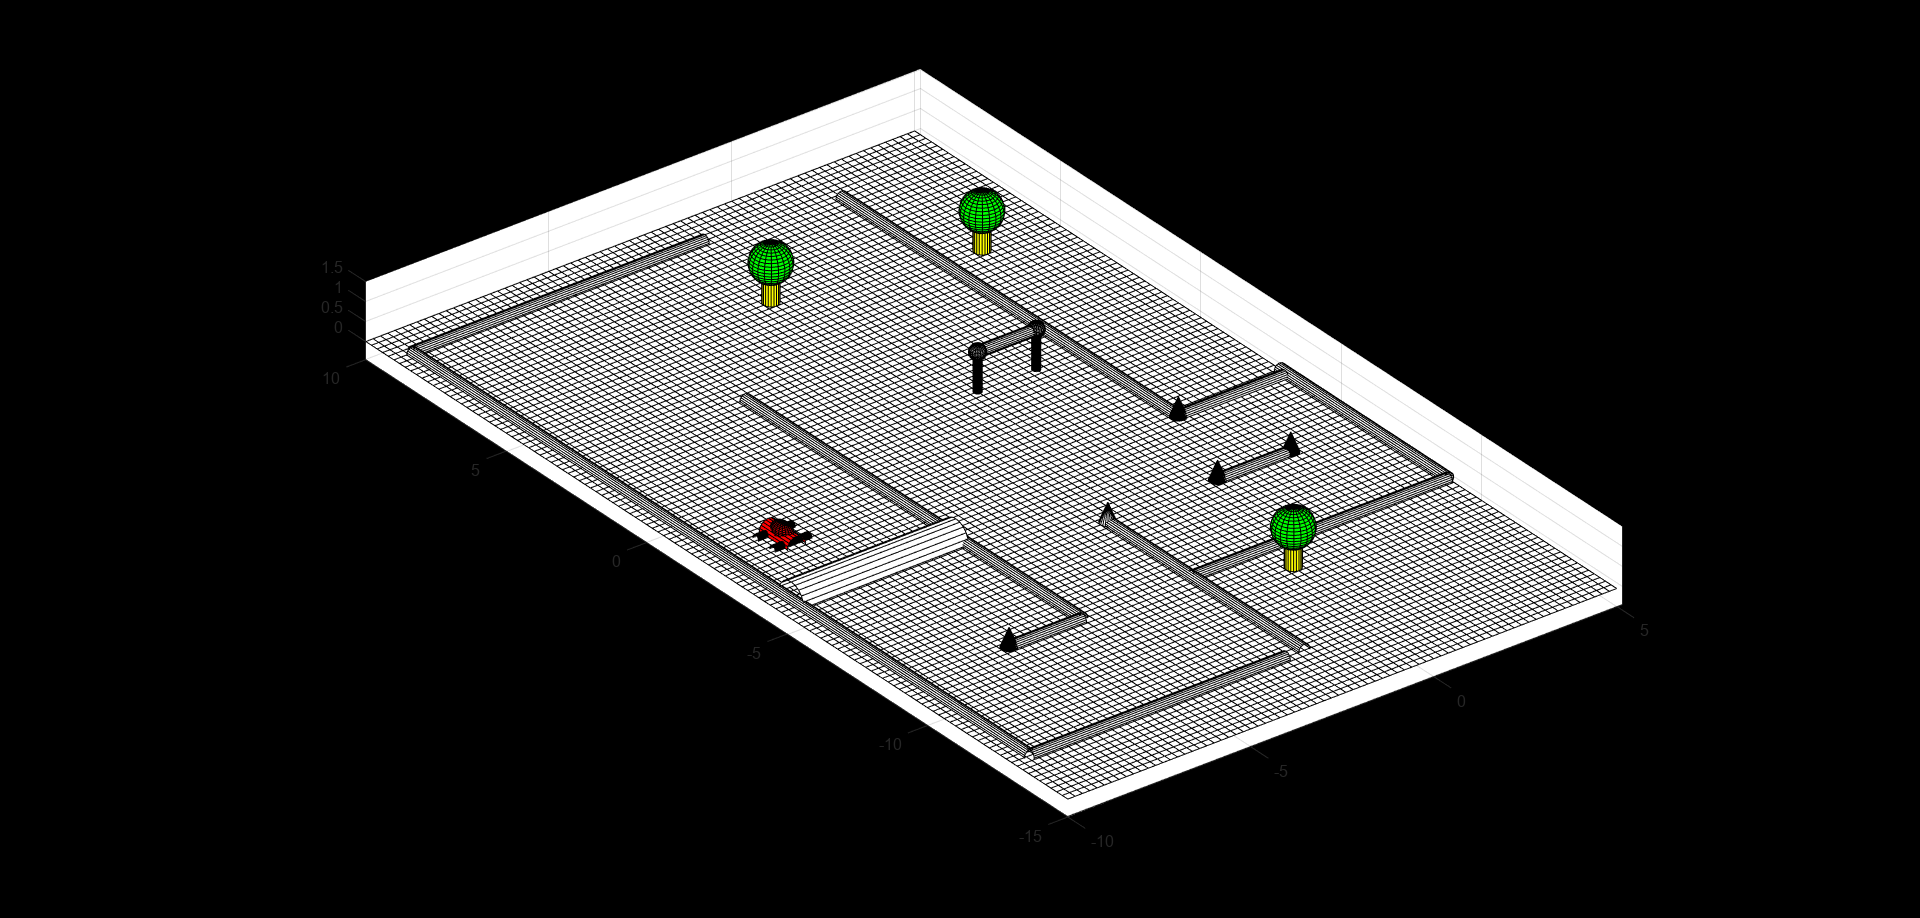

m=0:.05:3/4*pi;
xmove=2*cos(m)-2;
ymove=2*sin(m)+6;
zbea=m-m.*(m-3*pi/4);

for i=1:numel(xmove)
    trans=makehgtform('translate',[xmove(i) ymove(i) 0]);
    rotz=makehgtform('zrotate',zbea(i));
    set(t,'matrix',trans*rotz);
    pause(.005)
end




m=0:.25:4;
xmove1=2*cos(3*pi/4)-2-m;
ymove1=xmove1+2*sqrt(2)+8;

for i=1:numel(xmove1)
    trans=makehgtform('translate',[xmove1(i) ymove1(i) 0]);
    rotz=makehgtform('zrotate',3*pi/4);
    set(t,'matrix',trans*rotz);
    pause(.005)
end



m=3*pi/4:.05:pi;
xmove2=xmove1(length(xmove1))+2*cos(m)-2*cos(3*pi/4);
ymove2=ymove1(length(xmove1))+2*sin(m)-2*sin(3*pi/4);
zbea=m;

for i=1:numel(xmove2)
    trans=makehgtform('translate',[xmove2(i) ymove2(i) 0]);
    rotz=makehgtform('zrotate',zbea(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end



m=0:.2:6;
xmove3=xmove2(length(xmove2))+zeros(1,length(m));
ymove3=-m+ymove2(length(xmove2));

for i=1:numel(xmove3)
    trans=makehgtform('translate',[xmove3(i) ymove3(i) 0]);
    set(t,'matrix',trans);
    pause(.001)
end



m=0:.08:6;
xmove4=xmove3(length(xmove3))+zeros(1,length(m));
ymove4=-m+ymove3(length(xmove3));
zmove=-m.*(m-6)/4;
xbea=-m*2*pi/6;

for i=1:numel(xmove4)
    trans=makehgtform('translate',[xmove4(i) ymove4(i) zmove(i)]);
    rotx=makehgtform('xrotate',xbea(i));
    set(t,'matrix',trans*rotx);
    pause(.002)
end



m=0:.05:pi;
xmove5=xmove4(length(xmove4))-2*cos(m)+2;
ymove5=ymove4(length(xmove4))-2*sin(m);
zbea=m-m.*(m-pi)*1/1.7;

for i=1:numel(xmove5)
    trans=makehgtform('translate',[xmove5(i) ymove5(i) 0]);
    rotz=makehgtform('zrotate',zbea(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end



m=0:.6:4;
xmove6=xmove5(length(xmove5))+zeros(1,length(m));
ymove6=ymove5(length(xmove5))+m;


for i=1:numel(xmove6)
    trans=makehgtform('translate',[xmove6(i) ymove6(i) 0]);
    set(t,'matrix',trans);
    pause(.01*pi)
end

m=0:.05:pi;
xmove7=xmove6(length(xmove6))-2*cos(m)+2;
ymove7=ymove6(length(xmove6))+2*sin(m);
zbea7=-m+m.*(m-pi)/2;

for i=1:numel(xmove7)
    trans=makehgtform('translate',[xmove7(i) ymove7(i) 0]);
    rotz=makehgtform('zrotate',zbea7(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end

m=0:.05:pi;
xmove8=xmove7(length(xmove7))-2*cos(m)+2;
ymove8=ymove7(length(xmove7))-2*sin(m);
zbea8=m-m.*(m-pi)/2-3.1645;

for i=1:numel(xmove8)
    trans=makehgtform('translate',[xmove8(i) ymove8(i) 0]);
    rotz=makehgtform('zrotate',zbea8(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end


m=0:.05:pi/2;
xmove9=xmove8(length(xmove8))+3.9961/2*cos(m)-3.9961/2;
ymove9=ymove8(length(xmove8))+3.9961/2*sin(m);
zbea9=m+m.*(m-pi/2)/2;

for i=1:numel(xmove9)
    trans=makehgtform('translate',[xmove9(i) ymove9(i) 0]);
    rotz=makehgtform('zrotate',zbea9(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end

m=0:.05:pi/2;
xmove10=xmove9(length(xmove9))-3.9961/2*sin(m);
ymove10=ymove9(length(xmove9))+3.9961/2*sin(m);
zbea10=-m+1.5339+m.*(m-pi/2)*1.25;

for i=1:numel(xmove10)
    trans=makehgtform('translate',[xmove10(i) ymove10(i) 0]);
    rotz=makehgtform('zrotate',zbea10(i));
    set(t,'matrix',trans*rotz);
    pause(.01)
end

m=0:.6:2.4171;
xmove11=xmove10(length(xmove10))+zeros(1,length(m));
ymove11=ymove10(length(xmove10))+m;
zbea11=0*m;

for i=1:numel(xmove11)
    trans=makehgtform('translate',[xmove11(i) ymove11(i) 0]);
    rotz=makehgtform('zrotate',zbea11(i));
    set(t,'matrix',trans);
    pause(.01*pi)
end



for i=1:2
    d=text(7,0,1,'\fontsize{16} {\color{magenta}NEW RECORD!}');
    pause(1)
    delete(d)
end

for i=1:1.5
    d=text(7,0,1,'\fontsize{16} {\color{magenta}Oh god, Its satwik winning the formula1 championship again !!!}');
    pause(1)
    delete(d)
end

for i=1:1.5
    d=text(7,0,1,'\fontsize{16} {\color{magenta}victory!!}');
    pause(1)
    delete(d)
end

m=0:.05:3;
xmove12=zeros(1,length(m));
ymove12=m;

for i=1:numel(xmove12)
    trans=makehgtform('translate',[xmove12(i) ymove12(i) 0]);
    set(t,'matrix',trans);
    pause(.003)
end

m=0:.05:2*pi;
xmove13=xmove12(length(xmove12))+2*cos(m)-2;
ymove13=ymove12(length(xmove12))+2*sin(m);
zbea13=m-m.*(m-2*pi)/5;




[xr yr zr]=cylinder([.3 .3]);

for i=1:numel(xmove13)
    trans=makehgtform('translate',[xmove13(i) ymove13(i) 0]);
    rotz=makehgtform('zrotate',zbea13(i));
    set(t,'matrix',trans*rotz);
    
    r(1) = surface(.2*xr+xmove13(i)-.2,.2*yr+ymove13(i),.05*zr,'FaceColor','black');
    r(2) = surface(.2*xr+xmove13(i)+.2,.2*yr+ymove13(i),.05*zr,'FaceColor','black');
    rr = hgtransform('Parent',ax);
    set(r,'Parent',rr)
    set(gcf,'Renderer','opengl')
    drawnow
    hold on
    
    pause(.01)
end


m=0:.25:5;
xmove14=xmove13(length(xmove13))+zeros(1,length(m));
ymove14=ymove13(length(xmove13))+m;
xbea14=m/5;

for i=1:numel(xmove14)
    trans=makehgtform('translate',[xmove14(i) ymove14(i) 0]);
    rotx=makehgtform('xrotate',xbea14(i));
    set(t,'matrix',trans*rotx);
    pause(.001)
end

m=0:.25:7;
xmove15=xmove14(length(xmove14))+zeros(1,length(m));
ymove15=ymove14(length(xmove14))+m;
xbea15=xbea14(length(xmove14))+0*m;

for i=1:numel(xmove15)
    trans=makehgtform('translate',[xmove15(i) ymove15(i) 0]);
    rotx=makehgtform('xrotate',xbea15(i));
    set(t,'matrix',trans*rotx);
    pause(.001)
end

text(5,0,1,'\fontsize{40} {\color{magenta}See you next season guys!!}');